ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


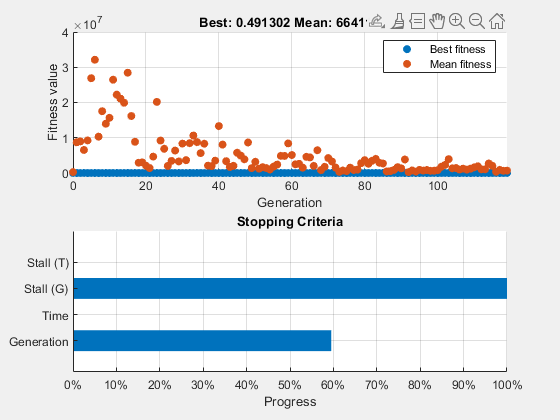

x =     0.3454    0.1444


fval = 0.4913

FitnessFcn = @dejong2fcn;
numberOfVariables = 2;

options = optimoptions(@ga,'PlotFcn',{@gaplotbestf,@gaplotstopping});

rng default
[x,fval] = ga(FitnessFcn,numberOfVariables,[],[],[],[],[],[],[],options)

Funcion Hibrida

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


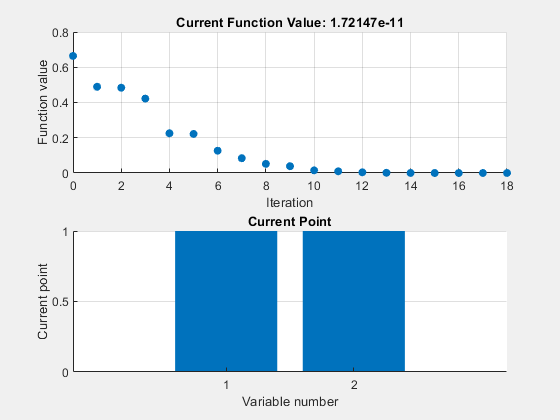


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


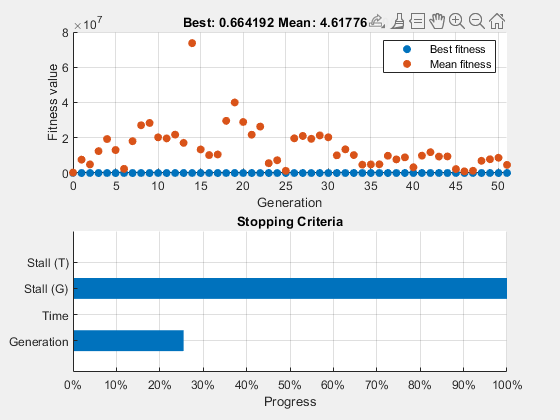

x =     1.0000    1.0000


fval = 1.7215e-11

exitflag = 1

output = struct with fields:
      problemtype: 'unconstrained'
         rngstate: [1×1 struct]
      generations: 51
        funccount: 2534
          message: 'ga stopped because the average change in the fitness value is less than options.FunctionTolerance.↵FMINUNC: Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the value of the optimality tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The first-order optimality measure, 2.473362e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.↵'
    maxconstraint: []
       hybridflag: 1


fminuncOptions = optimoptions(@fminunc,'PlotFcn',{'optimplotfval','optimplotx'});
options = optimoptions(options,'HybridFcn',{@fminunc, fminuncOptions});

[x,fval,exitflag,output] = ga(FitnessFcn,numberOfVariables,[],[],[],[],[],[],[],options)